# **demo01 of Im2mesh package**

demo01 - Demonstrate function im2mesh, which use MESH2D as mesh generator.

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D. We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Kumamon

Let's start demo01. We'll demostate the usage of function im2mesh.

Import image kumamon.tif.

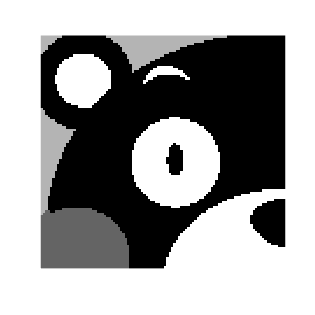

im = imread("kumamon.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Show the grayscale levels in the image

intensity = unique( im ); 
intensity

intensity = 4×1 uint8 column vector
     0
   100
   180
   255


Let's use function im2mesh to generate meshes based on the kumamon image. We will use default settings. Note that function im2mesh has incorporated the workflow that you saw in im2mesh_GUI: extract polygonal boundaries from image, search & label control points, smooth boundary, simplify boundary, select phase, and generate mesh.

[ vert, tria, tnum ] = im2mesh( im );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          8                156                229
         10                166                333
         15                178                527


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          8                274                229
         10                278                861
         19                285               1838


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                457               1824
          8                 75               1824



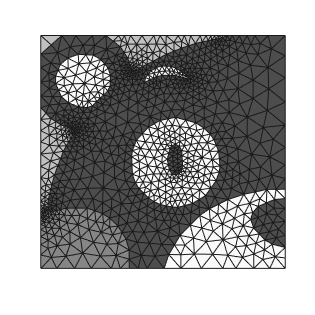

% plot mesh using function plotMeshes
plotMeshes( vert, tria, tnum )

## Mesh quality

We can use function tricost check the mesh quality.

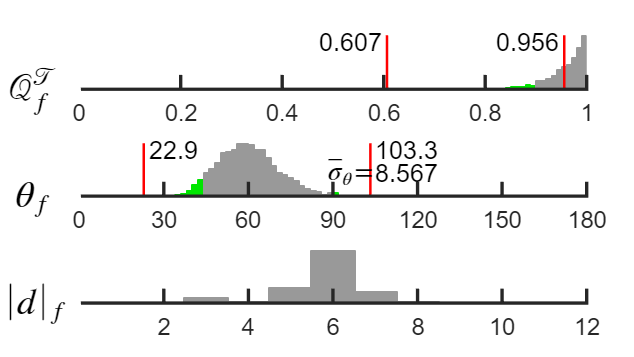

tricost( vert, tria, tnum )

We can get the mean value of Q.

mean(triscr2( vert, tria ))

ans = 0.9558

Wonderful! Let's check the total number of triangles in the mesh.

size( tria, 1 )

ans = 1824

That's a lot of triangles. 

## Change parameter

We can change the parameters of function im2mesh to see whether it help to reduce the number of triangles. 

opt = [];               % initialize. opt is a structure array.
opt.tolerance = 1;      % default value for opt.tolerance is 0.3

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                103                131
         10                118                233
         12                119                238


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                172                131
         10                183                588
         15                191                797


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                160                785
          8                 19                785



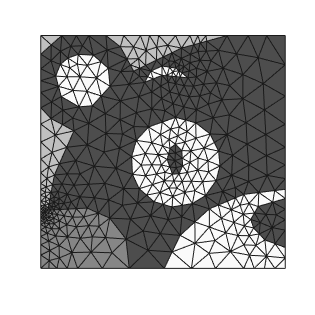

plotMeshes( vert, tria, tnum )

Now, the number of triangles decreased to 785. That's great.

## Parameters of function im2mesh

As I showed before, there're two ways to call function im2mesh.

Variable opt means options. It's a structure array used to stored input parameters for function im2mesh. We can take a look at the default value of opt.

You don't need to memorize the names of these parameters. The meaning of these parameters are listed the file "Im2mesh Function List and Parameters.pdf". Please refer to "Im2mesh_GUI Tutorial.pdf" about how to choose the value of these parameters. You can change these default values by editting function setOption in "im2mesh.m".

## Example 1

Let's show some examples with different opt.

% example 1
opt = [];               % reset opt
opt.tolerance = 0;      % no polyline simplification
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                750               1406
         10                784               1987
         20                803               3856
         20                803               3856


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                901               1406
         10                904               4976
         20                917              10825
         21                917              10829


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

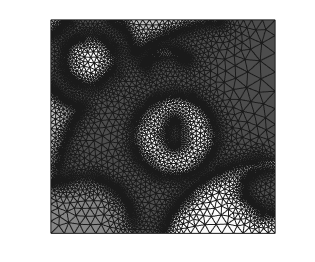

plotMeshes( vert, tria, tnum );

## Example 2

% example 2
opt = [];                       % reset opt
opt.tolerance = 1;
opt.select_phase = [1 2 4];     % select phase for meshing
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 87                119
          9                100                198


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                145                119
         10                158                640
         13                162                698


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                145                688
          8                  8                688



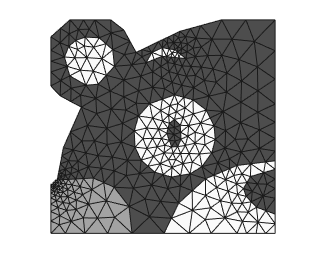

plotMeshes( vert, tria, tnum );

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo